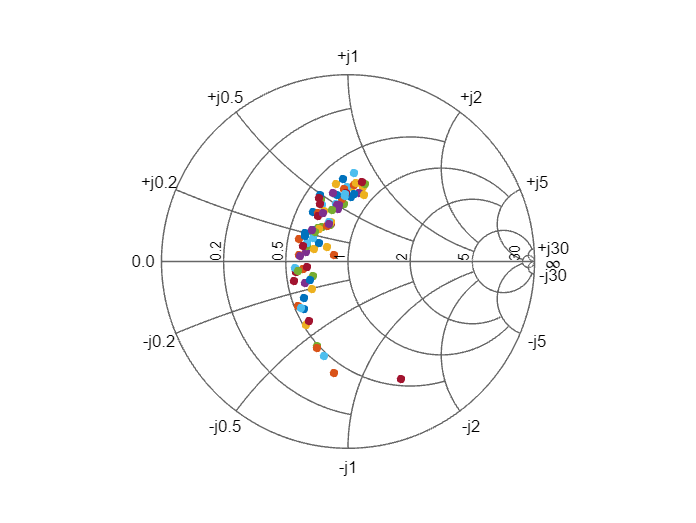

DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\30mm_Copper_SilverEpoxy\Smith Chart\";
DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\30mm\Smith Chart\";
DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\26mm\Smith Chart\";
DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\24mm\Smith Chart\";

FileNames = [
    "PF T1.xlsx";
    "PF T2.xlsx";
    "PF T3.xlsx";
    "PF T4.xlsx";
    "PF T5.xlsx";
    "PF T6.xlsx";
    "PF T7.xlsx";
    "PF T8.xlsx";
    "PF T9.xlsx";
    "PF T10.xlsx";
    "PF T11.xlsx";
    "PF T12.xlsx";
    "PF T13.xlsx";
    "PF T14.xlsx";
    "PF T15.xlsx";
    "PF T16.xlsx";
    "PF T17.xlsx";
    "PF T18.xlsx";
    "PF T19.xlsx";
    "PF T20.xlsx";
    "PF T21.xlsx";
    "PF T22.xlsx";
    "PF T23.xlsx";
    "PF T24.xlsx";
    "PF T25.xlsx";
    "PF T26.xlsx";
    "PF T27.xlsx";
    "PF T28.xlsx";
    "PF T29.xlsx";
    "PF T30.xlsx";
    ];

FileCount = 1:30;


FileNames2 = [
    "PF T1.csv";
    "PF T2.csv";
    "PF T3.csv";
    "PF T4.csv";
    "PF T5.csv";
    "PF T6.csv";
    "PF T7.csv";
    "PF T8.csv";
    "PF T9.csv";
    "PF T10.csv";
    "PF T11.csv";
    "PF T12.csv";
    "PF T13.csv";
    "PF T14.csv";
    "PF T15.csv";
    "PF T16.csv";
    "PF T17.csv";
    "PF T18.csv";
    "PF T19.csv";
    "PF T20.csv";
    "PF T21.csv";
    "PF T22.csv";
    "PF T23.csv";
    "PF T24.csv";
    "PF T25.csv";
    "PF T26.csv";
    "PF T27.csv";
    "PF T28.csv";
    "PF T29.csv";
    "PF T30.csv";
    "PF T31.csv";
    "PF T32.csv";
    "PF T33.csv";
    "PF T34.csv";
    "PF T35.csv";
    "PF T36.csv";
    "PF T37.csv";
    "PF T38.csv";
    "PF T39.csv";
    "PF T40.csv";
    "PF T41.csv";
    "PF T42.csv";
    "PF T43.csv";
    "PF T44.csv";
    "PF T45.csv";
    "PF T46.csv";
    "PF T47.csv";
    "PF T48.csv";
    "PF T49.csv";
    "PF T50.csv";
    "PF T51.csv";
    "PF T52.csv";
    "PF T53.csv";
    "PF T54.csv";
    "PF T55.csv";
    "PF T56.csv";
    "PF T57.csv";
    "PF T58.csv";
    "PF T59.csv";
    "PF T60.csv";
    "PF T61.csv";
    "PF T62.csv";
    "PF T63.csv";
    "PF T64.csv";
    "PF T65.csv";
    "PF T66.csv";
    "PF T67.csv";
    "PF T68.csv";
    "PF T69.csv";
    "PF T70.csv";
    "PF T71.csv";
    "PF T72.csv";
    "PF T73.csv";
    "PF T74.csv";
    "PF T75.csv";
    "PF T76.csv";
    "PF T77.csv";
    "PF T78.csv";
    "PF T79.csv";
    "PF T80.csv";
    "PF T81.csv";
    "PF T82.csv";
    "PF T83.csv";
    "PF T84.csv";
    "PF T85.csv";
    ];

FileCount2 = 1:85;

% figure;
%     for loopFiles = FileCount
%         VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
%         Freq = VNA_Zdata(134,1);
%         Real = VNA_Zdata(134,2);
%         Imag = VNA_Zdata(134,3);
% 
%         i = sqrt(-1);
%         Z = Real + (Imag*i);
%         Z0 = 50; %Characteristic impedance 50 0hm's
%         S11 = (Z-Z0)./(Z+Z0); %<--- complex number %This IS NOT the magnitude.
%         smithplot(Freq, S11,'.', 'MarkerSize', 15);    
%         hold on;
%     end


% figure('Position', [1, 1, 1200, 800], 'Color',[1 1 1])
% t = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');
% xlabel(t, " Measurement # Corresponding to a Different Testbed Implantation Location ", 'FontSize', 11);
% ylabel(t, " |S_{11}| { dB } @ 433 MHz ", "FontSize", 11);


figure('Color', [1,1,1]);
plotSmith(DirectoryName, FileNames2, FileCount2);

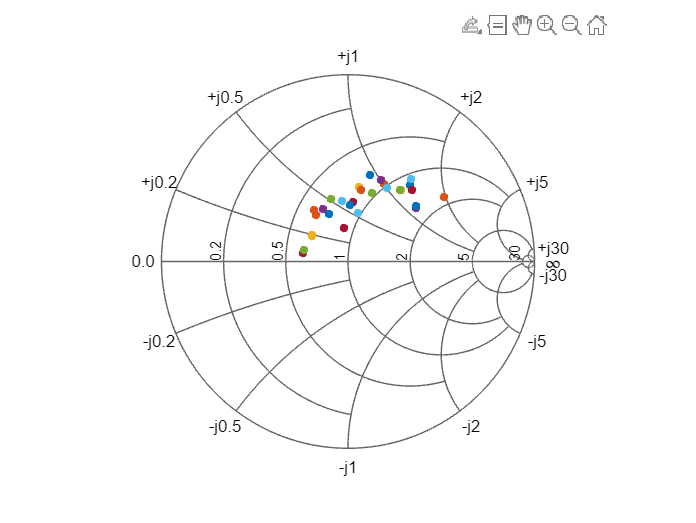



figure('Color', [1,1,1]);
plotSmith(DirectoryName2, FileNames, FileCount);

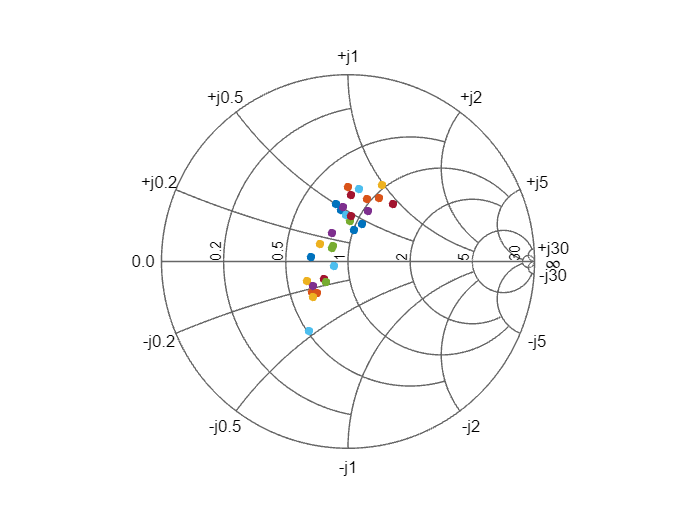

% xlabel(" (b) ", 'FontWeight', 'bold', 'FontSize', 11);


figure('Color', [1,1,1]);
plotSmith(DirectoryName3, FileNames, FileCount);

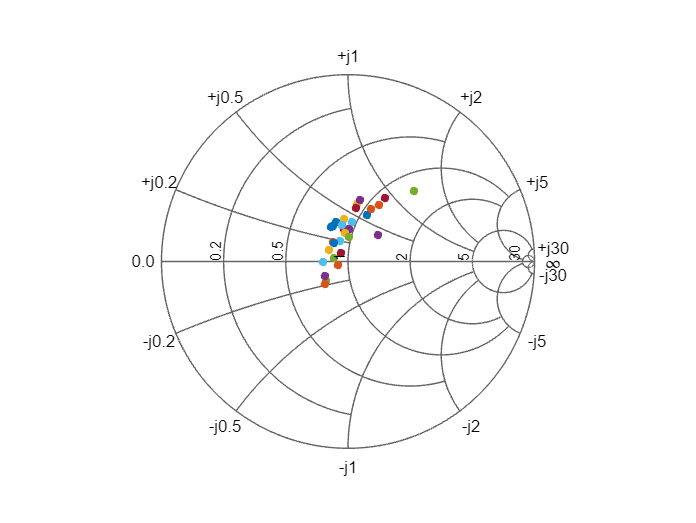

% xlabel(" (c) ", 'FontWeight', 'bold', 'FontSize', 11);


figure('Color', [1,1,1]);
plotSmith(DirectoryName4, FileNames, FileCount);

% xlabel(" (d) ", 'FontWeight', 'bold', 'FontSize', 11);


function [y] = plotSmith(DirectoryName, FileNames, FileCount) %Smith Chart Version for single frequency.

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        Freq = VNA_Zdata(134,1);
        Real = VNA_Zdata(134,2);
        Imag = VNA_Zdata(134,3);

        i = sqrt(-1);
        Z = Real + (Imag*i);
        Z0 = 50; %Characteristic impedance 50 0hm's
        S11 = (Z-Z0)./(Z+Z0); %<--- complex number %This IS NOT the magnitude.
        y = smithplot(Freq, S11,'.', 'MarkerSize', 15); 
        % y = smithplot(Freq, S11);
        hold on;
    end
end